% Define a range for lambda (0 to 2, step size 0.01)
lambdavals=0.98:0.00001:1.02;
% Initialize a vector of f values for each lambda
f=zeros(1,length(lambdavals));
% Define a function to integrate
func = @(x, lambda) exp(-100*(x-2).^2).*exp(50i*(x-lambda/32*x.^4));
% Iterate over all lambda positions
max = 0

max = 0

maxlambda = 0

maxlambda = 0

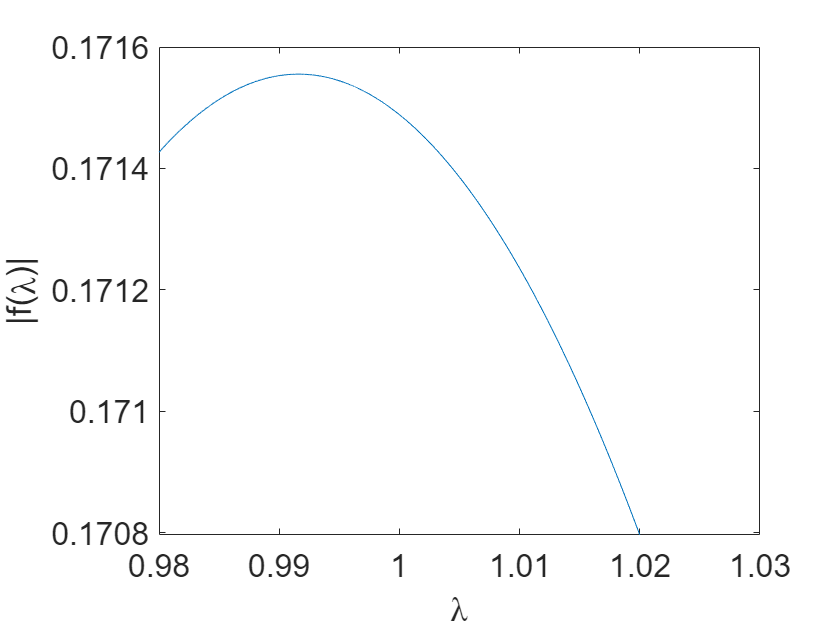

for i = 1:length(lambdavals)
    % Integrate to obtain the value of f(lambda).
    % We integrate from -10 to 10
    f(i) = integral(@(x) func(x, lambdavals(i)), -10, 10);
    if abs(f(i)) > max
        max = abs(f(i));
        maxlambda=lambdavals(i);
    end
end

% lambdavals is a vector of values of lambda
% f is a corresponding vector of values f(lambda)

% Plot |f|
p=plot(lambdavals, abs(f));
p.Parent.FontSize = 16;
xlabel('\lambda');
ylabel('|f(\lambda)|');


% Compute f(lambda) at a specific lambda
lambda=1;
fl=integral(@(x) func(x, lambda), -10, 10);
mag=abs(fl);
phase=angle(fl);
if phase < 0
    phase=phase+2*pi;
end
disp(['f(lambda=',num2str(lambda),')=',num2str(mag,8),'*exp(i*',num2str(phase/pi),'*pi); maxlambda=',num2str(maxlambda)])

f(lambda=1)=0.17148857*exp(i*1.8162*pi); maxlambda=0.99161
